# Inne algorytmy

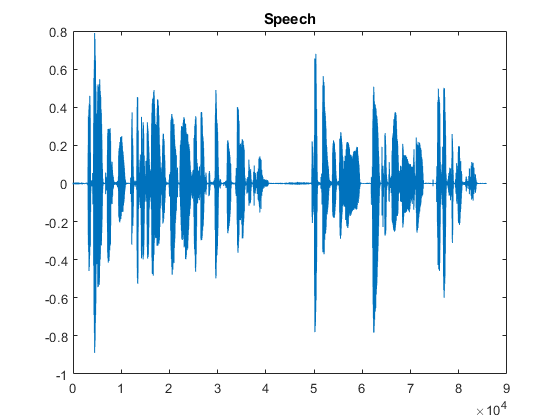

ifigs = 0;             %  0/1 - to show figures inside the processing loop?

% Parameters
Mlen=240;              % length of analyzed block of samples
Mstep=180;             % offset between analyzed data blocks (in samples)
Np=2;                  % prediction order (IIR-AR filter order)
where=181;             % initial position of the first voiced excitation
roffset=20;            % offset in auto-correlation function when find max
compress=zeros(3,6);   % table for calculated speech model coefficients
s=[];                  % the whole synthesized speech
ss=[];                 % one fragment of synthesized speech

% Read signal to compress
[x,fs]=audioread('mowa1.wav');	   % read speech signal (audio/wav/read)
figure; plot(x); title('Speech');  % display it

%soundsc(x,fs);% pause               % play it on loudspeakers (headphones)
N=length(x);                       % signal length
bs=zeros(1,Np);			   % synthesis filter buffer
Nblocks=floor((N-Mlen)/Mstep+1);   % number of speech blocks to be analyzed

for  nr = 1 : Nblocks
    % take new data block (fragment of speech samples)
    n = 1+(nr-1)*Mstep : Mlen + (nr-1)*Mstep;
    bx = x(n);
    
    for k = 0 : Mlen-1
        r(k+1)=sum( bx(1:Mlen-k) .* bx(1+k:Mlen) ); % calculate auto-correlation
    end                                             % try: r=xcorr(x,'unbiased')
    if(ifigs==1)
        subplot(411); plot(n,bx); title('Input speech x(n)');
        subplot(412); plot(r); title('Its auto-correlation rxx(k)');
    end
    [rmax,imax] = max( r(roffset : Mlen)  );        % find max of auto-correlation
    imax = imax+(roffset-1);                        % its argument (position)
    
    if ( rmax > 0.35*r(1) )  T=imax; else T=0; end
    
    T1 = T;
    
    [T2, gain, power, a] = getAnalysed(bx, Mlen, compress((end-2):end,:));
    compress=[ compress; T1, T2, gain, power, a(1), a(2)];
    
    if (T~=0) where=where-Mstep; end            % next excitation=1 position
    for n=1:Mstep                               % SYNTHESIS LOOP START
        if(T==0)                               %
            % exc=2*(rand(1,1)-0.5); where=271;   % random excitation
            exc=0.5*randn(1,1); where=271;      % random excitation
        else                                    %
            if (n==where) exc=1; where=where+T;  % excitation = 1
            else exc=0; end                      % excitation = 0
        end                                     %
        ss(n) = gain*exc - bs*a;                % filtering excitation
        bs = [ss(n) bs(1:Np-1) ];               % shifting the output buffer
    end                                         % SYNTHESIS LOOP END
    s = [s ss];                                 % store the synthesized speech
    if(ifigs==1) subplot(414); plot(ss); title('Synthesized speech s(n)'); end
end

harmonic tile
harmonic tile
harmonic tile
harmonic tile
harmonic tile
harmonic tile
harmonic tile
harmonic tile


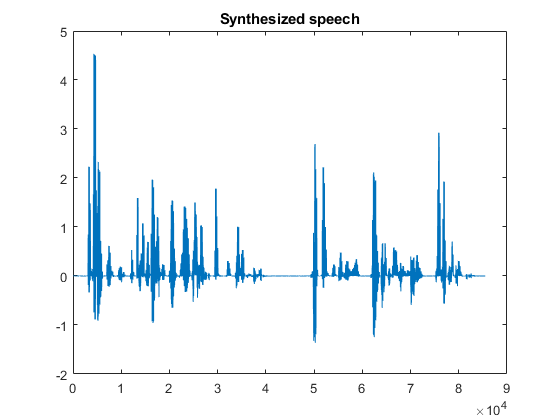


figure; plot(s); title('Synthesized speech');

%soundsc(s,fs)


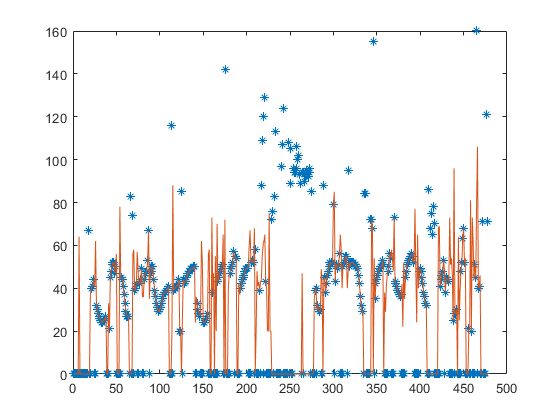

figure
plot(compress(:,1), '*')
hold on
plot(compress(:,2), '-')

function [T, gain, bxRMS, a] = getAnalysed(bx, Mlen, recent_compress)
% global roffset; global Np;
roffset = 20; Np = 2;
w = [0.3 0.3 9e-6 0.01];                         % constatns (P1, P2, RMS^2, P3)
p = 0;                                          % probability of bezdzwieczna

bx = bx - mean(bx);                             % remove mean value
for k = 0 : Mlen-1
    r(k+1)=sum( bx(1:Mlen-k) .* bx(1+k:Mlen) ); % calculate auto-correlation
end
bxRMS = rms(bx)^2;

Fs = 8e3;

% based on bxRMS
if(bxRMS < w(3))
    p = p + w(2);
end

% get fft of signal
if(true)
    %if(p < w(2))
    Y = abs(fft(bx));
    P2 = abs(Y/Mlen);
    P1 = P2(1:Mlen/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(Mlen/2))/Mlen;
    %figure(2)
    %plot(f,P1)
    
    
    % take k maximum val
    
    [I, B] = maxk(P1,4);
    
    sub = [];
    sub(1) = B(1)-B(2);
    sub(2) = B(1)-B(3);
    sub(3) = B(1)-B(4);
    
    if(sub(1)*0.4>sub(2) || sub(2)*0.4 > sub(3))
        % +bezdzwieczna
        p = p + w(1);
    end
    
    div = [];
    div(1) = I(2)/I(1);
    div(2) = I(3)/I(1);
    div(4) = I(4)/I(1);
    
    for i=1:size(div,1)
        if(abs(round(div(i))-div(i)) < w(4))
            display('harmonic tile')
            % jest dzwieczna
            p = 0;
        end
    end
    
end



if(p > 0.5)
    T = 0;
else
    [rmax,imax] = max( r(roffset : Mlen)  );        % find max of auto-correlation
    imax = imax+(roffset-1);
    T=imax;
    if (T>80) T=round(T/2); end
end

R = [];
for m=1:Np                                  %
    R(m,1:Np)=[r(m:-1:2) r(1:Np-(m-1))];	 % build an auto-correlation matrix
end

rr(1:Np,1)=(r(2:Np+1))';
a=-inv(R)*rr;                               % find coeffs of LPC filter
gain=r(1)+r(2:Np+1)*a;                      % find filter gain
H=freqz(1,[1;a]);
end

% inv implementation based on Levison algorithm
function invR = myInv(R)

end